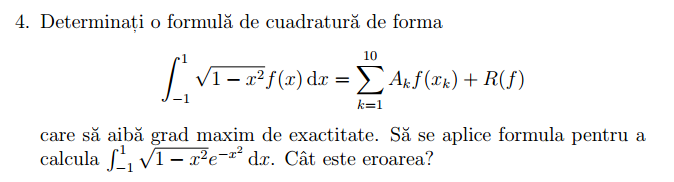

n = 10;
f = @(x) exp(-x.^2);

% Compute nodes and weights using Gaussian quadrature for Chebyshev Type II
[nodes, weights] = gauss_chebyshev2(n);

% Apply quadrature
I_approx = sum(weights .* f(nodes));

% Compute exact value numerically
f_weighted = @(x) sqrt(1 - x.^2) .* exp(-x.^2);
I_exact = integral(f_weighted, -1, 1, 'AbsTol', 1e-12);

% Compute error
error = abs(I_exact - I_approx);

% Display results
fprintf('Chebyshev Type II Quadrature (n = 10):\n');

Chebyshev Type II Quadrature (n = 10):


fprintf('Approximate value: %.10f\n', I_approx);

Approximate value: 1.2589242566


fprintf('Exact value:       %.10f\n', I_exact);

Exact value:       1.2589242566


fprintf('Absolute error:    %.2e\n', error);

Absolute error:    2.63e-13
